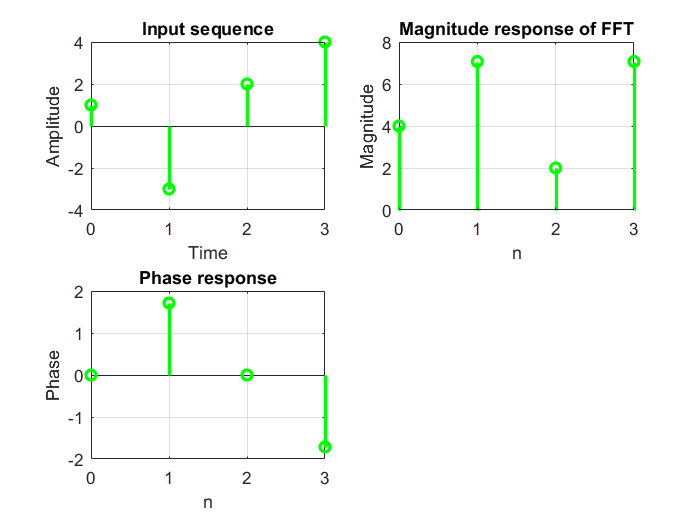

clc;
clear all;
close all;

% Input sequence
x = input('Enter the sequence : ');
N = length(x);    % Get the length of the input sequence

% Compute FFT of the input sequence
xk = fft(x);

% Time indices
n = 0:N-1;

% Plot the input sequence
subplot(2,2,1);
stem(n, x, 'Color', 'g','linewidth',2);
xlabel('Time');
ylabel('Amplitude');
title('Input sequence');
grid on;

% Plot the magnitude of the FFT
subplot(2,2,2);
stem(n, abs(xk),'Color', 'g','linewidth',2);
xlabel('n');
ylabel('Magnitude');
title('Magnitude response of FFT');
grid on;

% Plot the phase of the FFT
subplot(2,2,3);
stem(n, angle(xk),'Color', 'g','linewidth',2);
xlabel('n');
ylabel('Phase');
title('Phase response');
grid on;